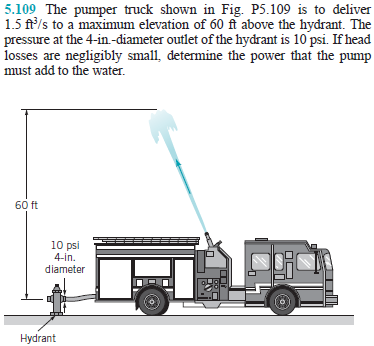

# inflow properties

u = symunit;
rho = 1.94*u.slug/u.ft^3;
Q = 1.5*u.ft^3/u.s;
p1 = 10*u.psi;
D1 = 4*u.in;
A1 = sympi*D1^2/4;
V1 = rewrite(Q/A1, 'US');
z1 = 0;

# outflow properties

p2 = 0;
V2 = 0;
z2 = 60*u.ft;

# mass flow rate

mdot = rho*Q;

# conservation of energy

g = 32.2*u.ft/u.s^2;
Wdotshaft = mdot*((p2-p1)/rho+(V2^2-V1^2)/2+g*(z2-z1));
Wdotshaft = rewrite(simplify(Wdotshaft), u.HP_UK);
Wdotshaft_vpa = vpa(Wdotshaft, 3) %#ok

$$Wdotshaft\_vpa = 5.51\,{\mathrm{HP}}_{\mathrm{UK}}$$

clear Wdotshaft_vpa;